### E101 Homework 9 - Part 1

#### Brock Bownds, Josue Meraz

**Part 1. Pulse Train Spectrum (10 points)**

A periodic pulse train with amplitude A, pulse train duration $2T_0$, and period $T_0$ is shown below:

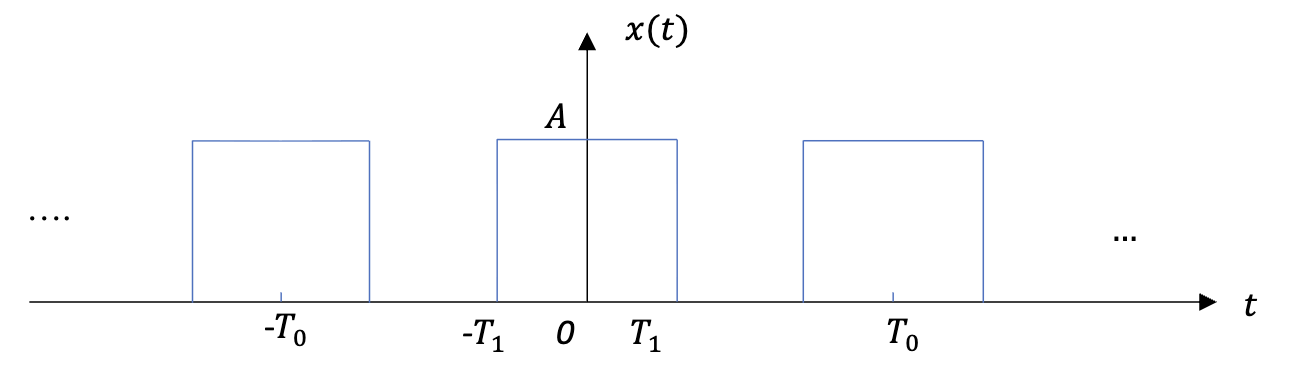

The file HW9.mat on Canvas contains a vector $x\left\lbrack n\right\rbrack \;$of sampled values from a periodic pulse train. It is obtained through a sampling process using a sample period $T_s$ = 10ms.

- Find the amplitude A and mean value $a_0$ of the sampled pulse train data. Estimate the period of the signal $T_0$ (in CT) by inspecting the time domain samples. Note that this is a rough estimate, since the true period may not be an integer multiple of the sampling rate.

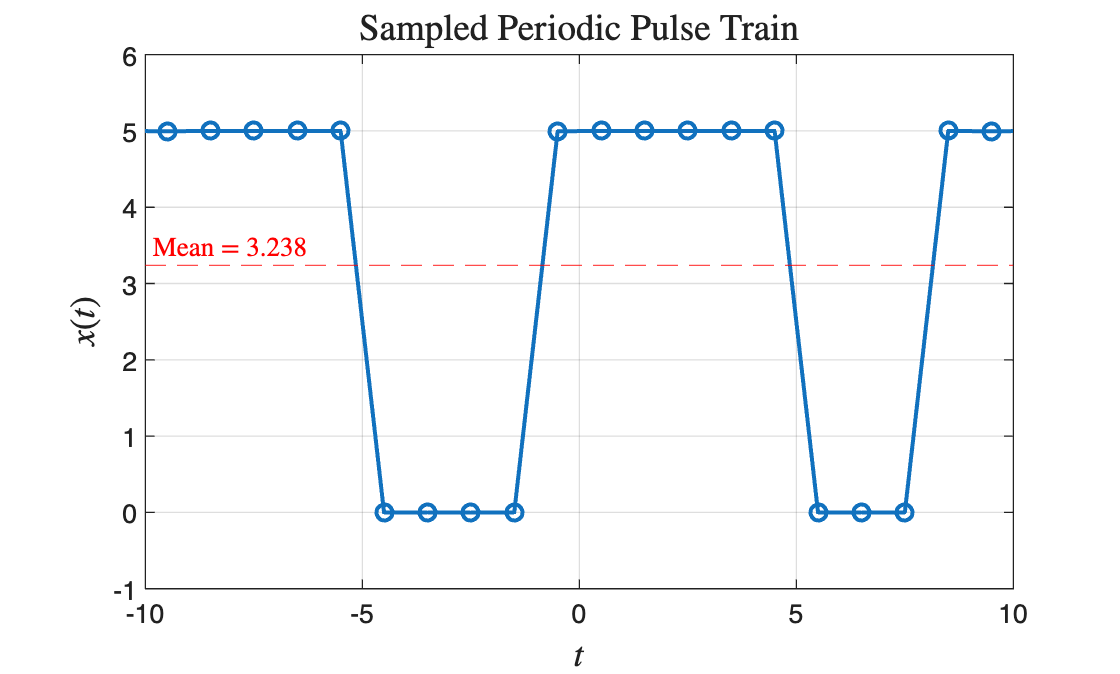

load('HW9.mat');  
n = length(x);

% Calculate mean value of sampled pulse train
mean_value = mean(x);       

plot(indices, x, 'o-', 'LineWidth', 1.5);
xlabel('$t$', 'Interpreter', 'latex', 'FontSize', 13);
ylabel('$x(t)$', 'Interpreter', 'latex', 'FontSize', 13);
title('Sampled Periodic Pulse Train', 'Interpreter', 'latex', 'FontSize', 14);
grid on;
xlim([-10 10]);
ylim([-1 6]);

hold on;
yline(mean_value, '--r', sprintf('Mean = %.3f', mean_value), ...
    'LabelHorizontalAlignment', 'left', 'Interpreter', 'latex');
hold off;

**               By inspection we can conclude the that the amplitude is A = 5, and through code calculation the mean value is **${\mathit{\mathbf{a}}}_0$ = **3.238.**